# Numerical Methods in Engineering

## Part 1: 16-bit floating point format.

**The half-precision (16-bit) floating point is one of the ways to store the numbers in computer memory. The half-precison has the following format,**

- **Sign Bit: 1 bit**

- **Exponent: 5 bits **

- **Mantissa: 10 bits  **

**a) The number of positive numbers that can be exactly represented in half-precision floating point format as normalized floating point values. The answer is expressed as a formula in terms of the number of bits in the Mantissa and in the Exponent, as well as the final value.**

*The number of positive numbers that can be exactly represented will consist of 10 Mantissa bits and 5 Exponent bits. The sign bit will be excluded from the computation because only positive values are considered. The 10 Mantissa bits can be used to represent *$2^{10} = 1024$ numbers. The 5 Exponent bits can be used to represent $2^{5} = 32$ numbers. *However, it must be taken into account that 00000 and 11111 are used for special cases to indicate positive/negative zero, subnormal values, positive infinitity, and NaN. Subtracting the special cases, the new number of bits that the Exponent can represent is *$30
$* numbers. *


$$\text{Number of Exactly Represented Positive Values} = {(2^{\text{Number of Exponent Bits}} - \text{Reserved Exponent Values}) \times {2^{\text{Number of Mantissa Bits}}} = (2^{5} - (2)) \times 2^{10} = 30720 \text{ numbers}$$


**b) The largest number that can be represented using half-precision format.**

*The largest number that can be represented using half-precision format will consist of all 1's in the Mantissa, which will be *$1111111111_2 = 1023_{10}$*. An Exponent that consists of all 11111 is used to represent either positive infinity or NaN, so the next available exponent that can be used is 11110. The bias can be calculated with the following equation *$\text{Bias} = 2^{5-1}-1 = 01111_2 = 15_{10}$. The exponent will therefore be $e = E - Bias = 11110_2 - 01111_2 = 30_{10}- 15_{10} = 15_{10}$. The final largest normal number $0 11110 1111111111_2 =   2^{15} \times (1 + \frac{2^{10}-1}{2^{10}}) = 65504_{10}$.

**c) The smallest normalized number that can be written in half-precision format.**

*The smallest normalized number that can be written in half-precision format must include at least one digit in the Exponent part of the number representation. The Exponent will therefore be 00001. Since there are no restrictions on the Mantissa, it can therefore be all zeros (e.g. 0000000000). The smallest normalized number is therefore *$0 00001 0000000000_2 = 2^{-14} \times (1 + \frac{0}{2^{10}}) \approx 0.000061035$.

**d) The smallest sub-normal (denormalized) number which can be represented in half-precision format.**

*The smallest sub-normal number that can be represented in half-precision format will have all 0's in the Exponent because that is the way to represent denormalized values. The Mantissa will have a single 1 in the location of the first bit*. *The final sub-normal value will be *$0 00000 0000000001_2 = 2^{-14} \times (0 + \frac{2^{0}}{2^{10}}) \approx 0.0000000596046$*. Note that the exponent is fixed at *$-14$* for subnormal half-precision format representations.*

**Sources used to complete this section: **

- [https://en.wikipedia.org/wiki/Half-precision_floating-point_format](https://en.wikipedia.org/wiki/Half-precision_floating-point_format)

- [https://stackoverflow.com/questions/8341395/what-is-a-subnormal-floating-point-number](https://stackoverflow.com/questions/8341395/what-is-a-subnormal-floating-point-number)

- [https://evanw.github.io/float-toy/](https://evanw.github.io/float-toy/)

- [https://www.h-schmidt.net/FloatConverter/IEEE754.html](https://www.h-schmidt.net/FloatConverter/IEEE754.html)

## Part 2: Summing elements. 

**By default MATLAB uses double precision format (i.e. 64-bit floating point fomat) to store the numbers. However,  we can store a number in computer memory in different floating-point format. For example, we can store a number in half precision (16-bit) format using the half() function to define a variable. Any computations thus made using this variable will be stored in the half-precision format. A Fixed Point Designer is needed to use half().**

doubles_sum = double(0); 
half_sum = half(0); 
doubles_sum_flipped = double(0);
half_sum_flipped = half(0);
doubles_vector = 1:10000;
doubles_vector_flipped = fliplr(1:10000);

**a) A MATLAB program that sums up **$\frac{1}{n}$** for **$n = 1, 2, . . . , 10000$** in double format (the default format in MATLAB).**

% Summing up largest to smallest values
for n = doubles_vector
    value = 1 ./ n;
    doubles_sum = doubles_sum + value;
end
disp(doubles_sum);

**b) A MATLAB program that sums  **$\frac{1}{n}$** for **$n = 1, 2, . . . , 10000$** in half precsion format.**

% Summing up largest to smallest values
for n = doubles_vector
    value = 1 ./ n;
    half_sum = half_sum + half(value);
end
disp(half_sum);

**c) A MATLAB program that sums  sums up the same airthmatic sequence in in reverse order, i.e., for **$n=10000,...,2,1$. 

% Summing up smallest to largest values
for n = doubles_vector_flipped
    value = 1 ./ n;
    half_sum_flipped = half_sum_flipped + half(value);
end
disp(half_sum_flipped);

for n = doubles_vector_flipped
    value = 1 ./ n;
    doubles_sum_flipped = doubles_sum_flipped + value;
end
disp(doubles_sum_flipped);

**Comparing the results obtatined in parts b) and c) with the results obtained in part a) and explaining the observations.**

*When numbers are summed from the largest to the smallest, substantial errors may arise due to the limited number of bits available for representation. This issue is particularly pronounced when there is a significant difference in magnitude between the numbers being added. Conversely, summing numbers from the smallest to the largest tends to yield less error, as the magnitudes of the values being added are more closely matched.*

*This phenomenon is evident in part a) of the analysis, where the use of double precision effectively mitigates significant errors. Double precision provides sufficient bits to accurately represent the addition of large and small numbers, especially towards the end of the computation when a large number is added with a small number. In part b), the truncation of each *$\frac{1}{n}$* number to half precision, as opposed to double precision, results in considerable representation errors. This leads to a final value of *$\approx ~7.0859$* that poorly represents the expected result.*

*Part c) introduces an adjustment to the summation approach, prioritizing the addition of smaller numbers first. This change in methodology demonstrates that while double precision representation is not significantly impacted by the order of summation, the substantial errors encountered with half precision representation can be markedly reduced by rearranging the order in which numbers are summed.*

**Sources used to complete this section: **

- [https://www.mathworks.com/help/fixedpoint/ref/half.html](https://www.mathworks.com/help/fixedpoint/ref/half.html)

## Part 3: **Computing the sum of the elements in a vector. **

**a) Running the following code cell to compute the sum of the elements in a vector. Explaining the discrepancy between the results obtained with MATLAB's built-in function and the analytical solution in part e).**

N = 30000000;
rng(200);                 % selecting random seed for reproducible results
XL = normrnd(1,0.1,N,1);  % generating normal random numbers
X  = single(XL);          % converting to single precision float

D_sum = sum(XL);  % using the double precision sum as the "exact" ground truth

tic
S1 = sum(X); % using built-in MATLAB function to compute the sum
toc

Elapsed time is 0.004620 seconds.




Error1 = abs(D_sum-S1)/D_sum  % comparing the results

Error1 = single
5.1897e-08

**b) A function S = naiveSum(X) that computes the sum of the values **$x_1$**, **$x_2$**, ..., **$x_n$** incrementally:**


$$S_1 = x_1 $$



$$S_2 = S_1 + x_2$$



$$\vdots$$



$$S_n = S_{n-1} + x_n$$


**The function is implemented using a for-loop in matlab.**

**Testing the function using the following code:**

N = 30000000;
rng(200);                 % selecting random seed for reproducible results
XL = normrnd(1,0.1,N,1);  % generating normal random numbers
X  = single(XL);          % converting to single precision float

D_sum = sum(XL);  % using the the double precision sum as the "exact" ground truth

tic
S2 = naiveSum(X); % using the function to compute the sum
toc

Elapsed time is 0.045307 seconds.



Error2 = abs(D_sum-S2)/D_sum  % comparing the results

Error2 = single
3.0919e-05

**c) A function S =  *****rSum(X) *****that uses recursion to compute the sum of the elements provided in the vector X. This approach is summarized as follows.**


$$S(X) = 
     \begin{cases}
       0 &\quad  \text{if   } n=0 \\
       x_1 &\quad \text{if   } n=1  \\
     S(X(1:n/2))+S(X(n/2 +1 : n) &\quad\text{if   } n>1 \\ 
     \end{cases}$$


**Note that **$n$** is the number of elements in X. Additionally the function addresses the case where **$\frac{n}{2}$** is not an integer. The following code is used to test the function.**

N = 30000000;
rng(200);                 % selecting random seed for reproducible results
XL = normrnd(1,0.1,N,1);  % generating normal random numbers
X  = single(XL);          % converting to single precision float

D_sum = sum(XL);  % using the the double precision sum as the "exact" ground truth

tic
S3 = rSum(X); % using the function to compute the sum
toc

Elapsed time is 8.750747 seconds.



Error3 = abs(D_sum-S3)/D_sum  % comparing the results

Error3 = single
5.1897e-08

**d) The recursive function calls add a significant amount of cpu cost in the algorithm in part c). A compromise algorithm is proposed, implemented, and tested. The algorithm uses both the naive and recursive approach and has both good accuracy and cpu cost. The imroved algorithm is compared to the MATLAB function sum and the design decision for the proposed algorithm is explained below. The algorithm is tested in the following code cell.**

N = 30000000;
rng(200);                 % selecting random seed for reproducible results
XL = normrnd(1,0.1,N,1);  % generating normal random numbers
X  = single(XL);          % converting to single precision float

D_sum = sum(XL);  % using the the double precision sum as the "exact" ground truth
tic
S4 = improvedSum(X); % using the function to compute the sum
toc 

Elapsed time is 0.268370 seconds.



Error4 = abs(D_sum-S4)/D_sum  % comparing the results

Error4 = single
1.4771e-08

*When deciding upon an improved solution that utilized both recursion and the naive strategy, the initial idea considered was tail recursion. However, subsequent testing of this approach revealed suboptimal performance, even falling short of conventional recursion in efficiency. Further investigation unveiled that MATLAB's environment lacks optimization for tail recursion, a feature commonly enhanced in functional programming languages, leading to its underperformance in comparison to alternative methodologies.*

*The finalized implementation integrates both naive and recursive methodologies, with a consideration of vector size to fine-tune both speed and memory utilization. For vectors with sizes less than the defined threshold, a straightforward iterative method is employed. Conversely, when dealing with vectors exceeding this threshold, the solution pivots to a divide-and-conquer strategy. The vector is divided into two halves until it is deemed "small enough" to be summed directly using a naive approach. The sum of the two halves are added together to produce the final value.*

**e) Explaining the difference in accuracy and cpu cost for the above methods for computing the sum. **

`naiveSum:`* Utilizing a for-loop, *`naiveSum`* achieves its computation in approximately 0.05 seconds. This speed demonstrates that, despite for-loops being generally less efficient in interpreted languages like MATLAB, they can still perform quite effectively for straightforward, linear tasks. However, this method exhibits a notable drawback in numerical accuracy demonstrated by the *$10^{-5}$* error. The inherent rounding errors that accumulate during the addition process—especially as the total sum becomes significantly larger than the magnitude of the numbers being added—lead to decreased precision. *

`rSum:T`*he recursive sum function, *`rSum`*, completes its computations in about 9 seconds, significantly slower than *`naiveSum`*. The recursive method, while being more accurate due to potentially minimizing rounding errors by handling smaller subsets of the vector, suffers from the overhead associated with recursive calls. Each call consumes stack space and incurs overhead for managing the call stack, which drastically affects performance. However, the approach can lead to slightly improved accuracy by addressing the precision issues inherent in sequential summation, especially for large datasets.*

`improvedSum:`* The *`improvedSum`* function represents a balance between the naive and recursive functions, completing computations in around 0.2 seconds. This method combines the divide-and-conquer approach with the simplicity of direct summation, optimizing both computation time and accuracy. By dividing the vector into manageable segments and summing those segments either directly or through further division, *`improvedSum`* effectively mitigates the accumulation of rounding errors seen in *`naiveSum`* while also avoiding the significant overhead introduced by deep recursion in *`rSum`*. This balanced approach leads to an enhanced accuracy over *`naiveSum`* and markedly improved performance compared to *`rSum`*.*

**Sources used to complete this section: **

- [https://www.mathworks.com/matlabcentral/answers/16309-tail-recursive-function-and-wrapper-function](https://www.mathworks.com/matlabcentral/answers/16309-tail-recursive-function-and-wrapper-function)

- [https://comp.soft-sys.matlab.narkive.com/6EASuG3E/matlab-optimizes-for-tail-recursion](https://comp.soft-sys.matlab.narkive.com/6EASuG3E/matlab-optimizes-for-tail-recursion)

- [https://www.mathworks.com/matlabcentral/answers/216376-how-do-i-define-the-recursive-function](https://www.mathworks.com/matlabcentral/answers/216376-how-do-i-define-the-recursive-function)

- [https://www.mathworks.com/matlabcentral/answers/257353-how-to-use-a-for-loop-to-calculate-the-sum-of-a-row-vector](https://www.mathworks.com/matlabcentral/answers/257353-how-to-use-a-for-loop-to-calculate-the-sum-of-a-row-vector)

## Part 4: Derivative Approximations.

**The derivative of a function**$f(x_0)$ **can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function: **

$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$**                    (4.1)**

**Rearranging terms to solve for **$f^{\prime } {\left(x_0 \right)}$**  and ignoring (truncating) the higher-order terms, the first order approximation is obtained:**

$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$**                                                                          (4.2)**

**a) Computing the truncation error for the above approximation. Explaining how the trunction error behave with a decrease in the value of **$h$ **below.**

                       
$$f(x_0+h)=f(x_0)+hf'(x_0)+\frac{1}{2!}f''(x_0)h^2+\frac{1}{3!}f'''(x_0)h^3+\ddots$$


*Using the Taylor Series expansion, the portion of the equation that is truncated is everything after *$f(x_0)+hf'(x_0)$, which is $t = \frac{1}{2!}f''(x_0)h^2+\frac{1}{3!}f'''(x_0)h^3+\ddots$.

*The derivative of a function equation *$f(x_0+h)$* can therefore be rewritten as *$f(x_0+h)=f(x_0)+hf'(x_0)+t$*. After rearanging the terms the equation becomes *$hf'(x_0) = f(x_0+h)-f(x_0)-t$*. Dividing by *$h$* gives *$f'(x_0) = \frac{f(x_0+h)-f(x_0)}{h}-\frac{t}{h}$*. The truncated portion *$\frac{t}{h}$* is the error *$T=\frac{t}{h}= \frac{1}{2!}f''(x_0)h+\frac{1}{3!}f'''(x_0)h^2+\ddots$*.*

*It can be concluded that the truncating error is T. The terms of the truncated part of the equation have a prefixed constant that is decreasing. As a result, the decreasing terms have an exponentially smaller influence on the resulting answer.*

**b) To compute the derivative of **$f (x) = sin(x)$**, equation (4.2) can be used.**

                        $\frac{d sin(x_0)} {dx}  \approx$ $\frac{\sin {\left(x_0 +h\right)}-\sin {\left(x_0 \right)}}{h}$**                                                                                                   (4.3)**

**In the cell below, a MATLAB program computes the derivative of **$sin(x_0)$** at **$x_0=45$** for different values of **$h$**. In particular, the values are **$h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$**.**

**The true value of derivative of **$sin(x_0)$** at **$x_0=45$** is **$cos(45)$**. The absolute error vs **$h$** is additionally plotted below. The axis are labeled and the plot has an appropriate title.**

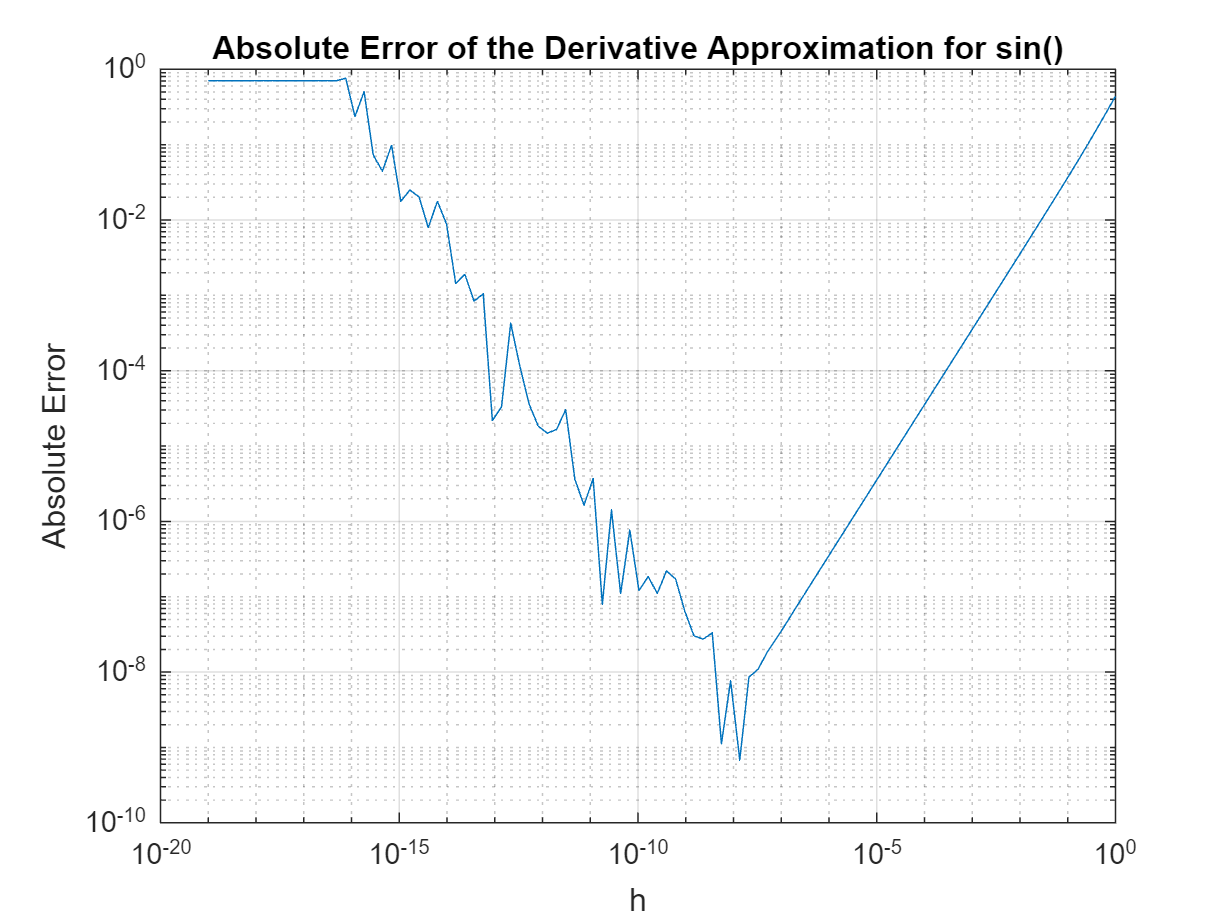

h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1
x_radians = deg2rad(45);
sin_derivative = (sin(x_radians + h) - sin(x_radians)) ./ h;
absolute_error = abs(cos(x_radians) - sin_derivative);
loglog(h, absolute_error);
xlabel('h');
ylabel('Absolute Error');
title('Absolute Error of the Derivative Approximation for sin()');
grid on;  % adding a grid for better readability

**c) The function **$sin(x_0+h)-sin(x_0)$** can be transformed into another form using the trigonometric formula 4.4.**

                        $sin(\phi) - sin(\psi) = 2 cos(\frac{\phi+\psi}{2}) sin((\frac{\phi-\psi}{2})$**                                                                                                    (4.4)**

**Using the above formula, equation 4.3 is transformed to compute the derivative of **$sin(x_0)$**. A MATLAB program then computes the derivative of the **$sin(x_0)$** at **$x_0=45$** for **$h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$**.**

**The derivative obtained is compared with the true value and a plot of the absolute error vs **$h$** is created. The axis are labeled and the plot has an appropriate title.**

*Starting with the original derivative approximation and replacing *$f$* with *$sin$* the equation*$f^{\prime } {\left(x_0 \right)}\ \approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$*  becomes *$sin'(x_0) \approx \frac{sin{\left(x_0 +h\right)}-sin{\left(x_0 \right)}}{h}$*. Replacing *$sin'(x_0)$* with the equivalence from 4.4 *$sin'(x_0) \approx \frac{sin{\left(x_0 +h\right)}-sin{\left(x_0 \right)}}{h} \approx  \frac{2\cos \left(\frac{x_0 +h+x_0 }{2}\right)\sin \left(\frac{x_0 +h-x_0 }{2}\right)}{h}$*. After combining the terms, the final equation that is used to compute the derivative approximation and plot the absolute error is *$sin'(x_0) \approx \frac{2cos\left(\frac{2x_0+h}{2}\right)sin\left(\frac{h}{2}\right)}{h}$*. *

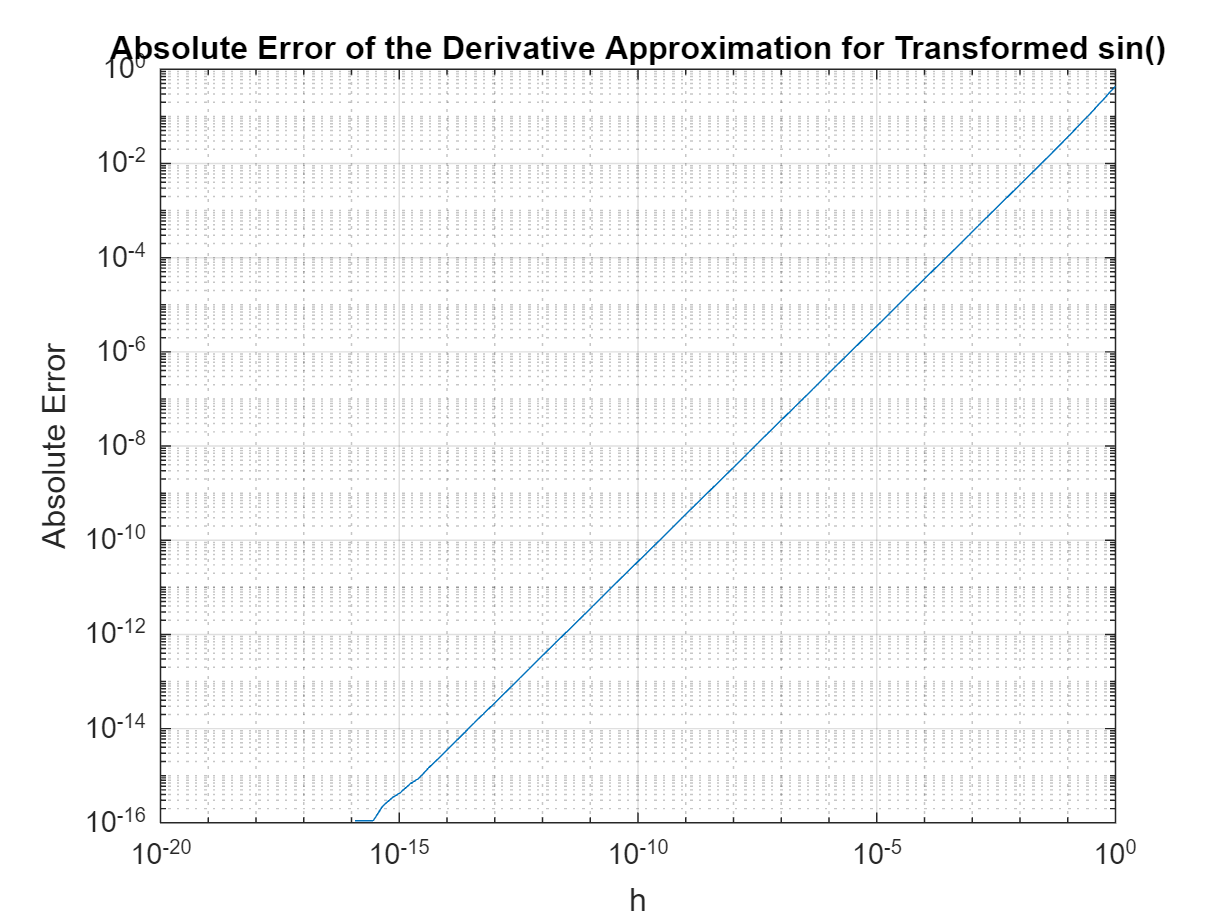

h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1
x_angle = deg2rad(45);
sin_derivative = (2 .* cos(((2.*x_angle)+h)./2) .* sin(h./2)) ./ h;
absolute_error = abs(cos(x_angle) - sin_derivative);
loglog(h, absolute_error);
xlabel('h');
ylabel('Absolute Error');
title('Absolute Error of the Derivative Approximation for Transformed sin()');
grid on;  % Add a grid for better readability

**d) Explaining the difference in accuracy between the results obtained in part b) and c). **

*In part b), catastrophic cancellation is evident for extremely small values of *$h$*, ranging from *$10^{-19}$* to *$10^{-16}$* where the absolute error peaks. This issue stems from the limitations of floating-point arithmetic: when a small increment *$h$* is added to a larger number *$x_0$*, the resultant sum may not be represented with sufficient precision, causing the sum *$x_0+h$* to be rounded to *$x_0$*. This rounding leads to significant errors in the calculation of *$sin(x_0+h) - sin(x_0)$*. As *$h$* increases to around *$h = 10^{-16}$*, the absolute error decreases, reaching a minimum where the balance between truncation error from the omitted higher-order terms and round-off error is optimal. Beyond this point, at *$h = 10^{-8}$*, the error increases due to the truncation error, as the finite difference quotient diverges from the true derivative by neglecting the more significant contributions of higher-order terms of the Taylor series.*

*In part c), the catastrophic cancellation resulting from the equation *$sin(x_0+h) - sin(x_0)$* is partially mitigated through the use of product forms involving *$sin$* and a *$cos$*. Despite this mitigation, the truncation of the Taylor series means that perfect approximation is unattainable. Choosing between catastrophic cancellation and a small approximation error, the latter is often considered a lesser of two inaccuracies. The plot in c) illustrates that as *$h$* increases, the error also increases, indicating a decrease in the accuracy of the derivative approximation. The absence of plot data below *$h \approx 10^{-16}$* is due to divisions by extremely small *$h$* values approaching zero, which get truncated to zero, leading to undefined or infinite results, which are not represented on the graph.*

**Sources used to complete this section: **

- [https://numpy.org/doc/stable/reference/generated/numpy.logspace.html](https://numpy.org/doc/stable/reference/generated/numpy.logspace.html)

- [https://www.mathworks.com/help/matlab/trigonometry.html](https://www.mathworks.com/help/matlab/trigonometry.html)

- https://www.mathworks.com/help/matlab/ref/loglog.html

## Part 5: Solving linear systems of equations. 

**a) A function *****forward_sub *****to perform the forward substitution on a lower triangular matrix is added in the appendix of the file. The function is verified by comparing the obtained results with MATLAB's built in backslash operator. **

**The cell below is used to test the correctness of the function on the provided lower triangular matrix.  **

L = tril(magic(4)); % A is a 4x4 LOWER triangular matrix   
b = [1; 2; 3; 4]; % right hand side vector of size 4x1

%---------------------------------------------------------------------------------------------------------
% Calling the forward_sub function and solving Ax = b (where A is a lower triangular square matrix).
y_expected = L \ b;
y_actual = forward_sub(L,b);
disp("Calculated `y` using forward_sub");

Calculated `y` using forward_sub


disp(y_actual);

    0.0625
    0.1534
    0.2273
   -1.8068



disp("Calculated `y` using \");

Calculated `y` using \


disp(y_expected);

    0.0625
    0.1534
    0.2273
   -1.8068



tolerance = 1e-5;
assert(all(abs(y_actual - y_expected) < tolerance), 'The actual result does not match the expected result.');

**b) A function *****backward_sub***** to perform the backward substitution on a lower triangular matrix is added in the appendix of the file. The function is verified by comparing the obtained results with MATLAB's built in backslash operator. **

**The cell below is used to test the correctness of the function on the provided upper triangular matrix.  **

U = triu(magic(4)); % A is a 4x4 UPPER triangular matrix   
b = [1; 2; 3; 4]; % right hand side vector of size 4x1

%---------------------------------------------------------------------------------------------------------
% Calling the backward_sub function and solving for Ax = b (where A is an upper triangular square matrix).
x_expected = U \ b;
x_actual = backward_sub(U,b);
disp("Calculated `x` using backward_sub");

Calculated `x` using backward_sub


disp(x_actual);

   -2.2926
    4.0909
   -7.5000
    4.0000



disp("Calculated `x` using \");

Calculated `x` using \


disp(x_expected);

   -2.2926
    4.0909
   -7.5000
    4.0000



tolerance = 1e-5;
assert(all(abs(x_actual - x_expected) < tolerance), 'The actual result does not match the expected result.');

**c) The function *****LU_decomposition***** in the Appendix of this file to compute the LU factorization using Gaussian Elimination. **

**d)  Using the LU decomposition implemented in part c) along with forward and backward substitution functions written in part a) and b), respectively, to solve the following system of equations. Displaying the values of vector X obtained.  **


$$\underset{A}{\underbrace{{\left[\begin{array}{cccc}
1e-16 & 50 & 5 & 9\\
0.2 & 5 & 7.4 & 5\\
0.5 & 4 & 8.5 & 32\\
0.89 & 8 & 11 & 92
\end{array}\right]}} } \underset{X}{\underbrace{{\left[\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right]}} } =\ \underset{b}{\underbrace{{\left[\begin{array}{c}
40\\
52\\
18\\
95
\end{array}\right]}} }$$


A = [1e-16, 50, 5, 9;
     0.2, 5, 7.4, 5;
     0.5, 4, 8.5, 32;
     0.89, 8, 11, 92];
b = [40; 52; 18; 95];

[L, U] = LU_decompositon(A);

y = forward_sub(L,b);
x = backward_sub(U,y);

disp("Calculated x values using LU_decompositon");

Calculated x values using LU_decompositon


disp(x);

 -426.3256
   -1.0469
   13.1250
    2.9688



disp("Residual of LU_decompositon");

Residual of LU_decompositon


disp(abs(A*x-b));

         0
   30.5308
   28.7878
   65.3048



**e) A function named *****LU_rowpivot *****to compute the Gaussian Elimination based LU factorization using the partial pivoting (row pivoting). The elements with maximum magnitude are chosen as pivots. The function should take matrix A as the input and should output L, U, and P matrices. The function is written in the Appendix of this file.**

**f) The cell below is used to test the LU decomposition with partial pivoting implemented in part b) along with forward and backward substitution functions written in part c) to solve the above system of equations. The values of vector X are displayed.  **

[L, U, P] = LU_rowpivot(A);

y = forward_sub(L,P*b);
x = backward_sub(U,y);
disp("Calculated x values using LU_rowpivot");

Calculated x values using LU_rowpivot


disp(x);

 -595.4623
   -2.1518
   21.6035
    4.3971



disp("Residual of LU_rowpivot");

Residual of LU_rowpivot


disp(abs(A*x-b));

   1.0e-13 *

    0.0711
    0.5684
    0.2842
    0.5684



**g) Commenting on the solutions obtained in part d) and f). Use the residual to determine which solution is more accurate.**

*When the pivot element in a matrix is either zero or nearly zero, proceeding with an LU decomposition without row exchanges leads to significant rounding errors. This is due to the limited precision of floating-point representation in computers, which may not sufficiently capture the significant digits resulting from computations involving such small numbers. Additionally, a pivot of zero would halt the decomposition process, as division by zero is undefined. Utilizing these numbers as pivots amplifies the problem, as subsequent division operations during elimination generate disproportionately large multipliers, thereby escalating any round-off errors. Such scenarios often result in substantial numerical errors, as can be observed in part d). The high residual values in d) signifies a less accurate approximation of *$X$*. *

*To circumvent these issues, row pivoting is used within the LU decomposition. This technique involves reordering the rows to position the largest element in absolute value as the pivot, thereby avoiding divisions by small numbers and preserving computation accuracy. The benefits of row pivoting is apparent in part f), where the significantly smaller residual—less than one—indicates minor approximation errors for *$X$* and highlights the improved precision attained by this approach.*

**Sources used to complete this section: **

- [https://www.youtube.com/watch?v=WgaFycuL8z0&ab_channel=JeffreyChasnov](https://www.youtube.com/watch?v=WgaFycuL8z0&ab_channel=JeffreyChasnov)

- https://www.youtube.com/watch?v=lOKTXOWi68Y

- http://buzzard.ups.edu/courses/2014spring/420projects/math420-UPS-spring-2014-reid-LU-pivoting.pdf

## Appendix

### Functions for Part 3.

function S = naiveSum(X)
    % S is the sum of all elements in vector X
    S = 0;
    for i = 1:length(X)
        S = S + X(i);
    end
end

%--------------------------------------------------------------------------
function S = rSum(X)
    % S is the sum of all elements in vector X
    size = length(X);
    if size == 0
        S = 0;
    elseif size == 1
        S = X(1);
    else
        midpoint = floor(size/2);
        S = rSum(X(1:midpoint)) + rSum(X(midpoint+1:size));
    end
end

%--------------------------------------------------------------------------
function S = improvedSum(X)
    % S is the sum of all elements in vector X
    size = length(X);
    if size < 10000
        S = 0;
        for i = 1:length(X)
            S = S + X(i);
        end
    else
        midpoint = floor(size/2);
        S = improvedSum(X(1:midpoint)) + improvedSum(X(midpoint+1:end));
    end
end

### Functions for Part 5.

function [L, U] = LU_decompositon(A)
    % L  is lower triagular matrix
    % U is upper triangular matrix 
    [rows, cols] = size(A);
    n = rows;
    L = eye(rows, cols);
    U = A;
    
    for i = 1:n-1
        pivot = U(i, i);
        if pivot == 0
            error('Division by zero.');
        end
        for j = i+1:n
            L(j, i) = U(j, i) / pivot; % multiplier
            U(j, i:n) = U(j, i:n) - L(j, i) * U(i, i:n);
        end
    end
end


function [L, U, P] = LU_rowpivot(A)
    % L  is lower triagular matrix
    % U is upper triangular matrix 
    % P is the permutation matrix
    % P*A = L*U

    [height, width] = size(A);
    L_length = height;
    L = zeros(L_length);
    U = A;
    P = eye(L_length);

    for current_col = 1:width-1
        
        current_row = current_col;

        t = U(current_row:end,current_col);
        t(t==0) = -Inf; 
        [pivot, pivot_index] = max(t);
        pivot_index = pivot_index + current_row -1;
        P([current_row,pivot_index],:) = P([pivot_index,current_row],:);
        U([current_row,pivot_index],:) = U([pivot_index,current_row],:);
        L([current_row,pivot_index],:) = L([pivot_index,current_row],:);
  
        if pivot == -Inf
            error("Cannot pivot on 0");
        else    
            for j = current_col+1:L_length
                L(j, current_col) = U(j, current_col) / pivot; % multiplier
                U(j, current_col:L_length) = U(j, current_col:L_length) - L(j, current_col) * U(current_col, current_col:L_length);
            end
        end
    end

    L = L + eye(L_length);
end

function y = forward_sub(L,b)
    % y is the vector
    % L is the lower triangular matrix
    n = length(b);
    y = zeros(n, 1);

    for i = 1:n
        if L(i, i) == 0
            error('Division by zero');
        end
        y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
    end
end 

function X = backward_sub(U,y)
    % X is the vector
    % U is the upper triangular matrix
    n = length(y);
    X = zeros(n, 1);

    for i = n:-1:1
        if U(i, i) == 0
            error('Division by zero');
        end
        X(i) = (y(i) - U(i, i+1:n) * X(i+1:n)) / U(i, i);
    end
end 